% Define units in meters
millimeter = 1e-3;  % 1 mm = 1e-3 meters
nanometer = 1e-9;   % 1 nm = 1e-9 meters
meter = 1;          % 1 m = 1 meter

% Speed of light in m/s
c = 3 * 10^8 * meter; % m/s

% Simulation points
N = 256;

% Size of simulation
D = %10x the aperture roughly, big enough to avoid error build up

% Light wavelength
lamb = 1000 * nanometer;

% Reflectivity of the output mirror
R = %Based off of analytic estimate, higher will guarentee the cavity to start

% Cavity mirror focal lengths, the curvature of a mirror can provide the same lensing as a non-vacuum material lens
f1 = 2.0 * meter;
f2 = 5 * meter;

% Parameters of the length L gain medium
Isat = 120 * 10^4;
alpha = 0.5;

% Power in Watts
power = 1;

% Power of random radiation, should be much less than our expected
% saturated power
power_random = 0.0001;

% Cavity length
L = 300 * millimeter;

% Number of bounces to make on the laser amplitude
iterations = 100;

% Roundtrip time for the beam assuming it is nearly axial
dt = 2 * L / c;

%Task:
%Implement grid_aperture(coordinates, r_outer, arm_thickness, N_x, N_y, sq = False)
%Where coordinates is the grid points to sample the aperture at,
% r_outer is the radius of a circular hole, or half the side length of a square hole
% if sq = True. Argument arm_thickness defines how thick to make the blocking bars,
% and N_x, N_y, give the number of gridlines or bars which run in the x and y 
% transverse directions.

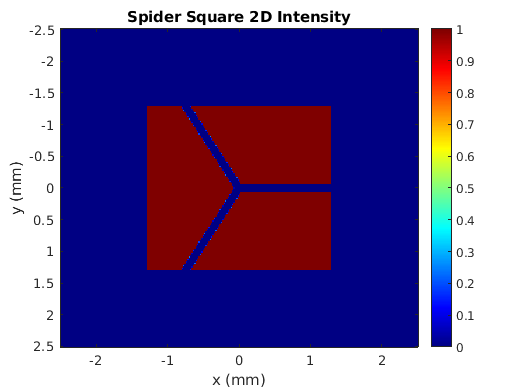

% Generate a simulation grid
gridcoords = generate_2d_coordinates(256, 5 * millimeter);

% Plot the spider aperture with square shape
spider_aperture_result = spider_aperture(gridcoords, 1.3 * millimeter, 0.1 * millimeter, 3, true);
plot_2d_intensity(gridcoords, spider_aperture_result, 'Spider Square');

drawnow;

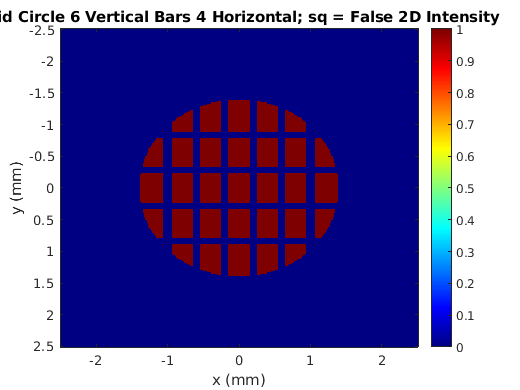

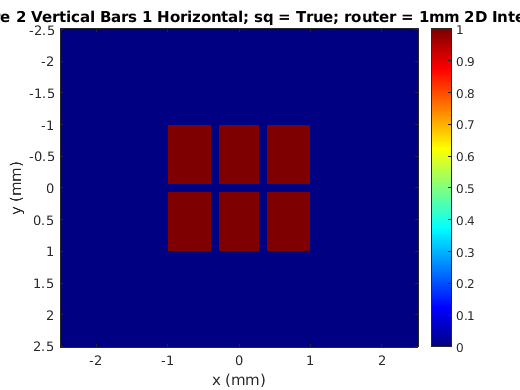

% Example apertures

% Grid aperture with circular shape and 6 vertical bars, 4 horizontal, square = False
aperture1 = grid_aperture(gridcoords, 1.4 * millimeter, 0.1 * millimeter, 6, 4, false);
plot_2d_intensity(gridcoords, aperture1, 'Grid Circle 6 Vertical Bars 4 Horizontal; sq = False');
drawnow;

% Grid aperture with square shape and 2 vertical bars, 1 horizontal, square = True
aperture2 = grid_aperture(gridcoords, 1 * millimeter, 0.1 * millimeter, 2, 1, true);
plot_2d_intensity(gridcoords, aperture2, 'Grid Square 2 Vertical Bars 1 Horizontal; sq = True; router = 1mm');

drawnow;

%Task: Implement random_amplitude(coordinates)
%This function should return an amplitude pattern where each amplitude 
% sample is randomly and independently identically distributed about zero. 
% The returned pattern should have amplitude normalized in the sense that the sum of
% square amplitude samples should be 1.0. 
% Careful use of normalization will allow the power and thus intensity of the beam
% to be kept track of.



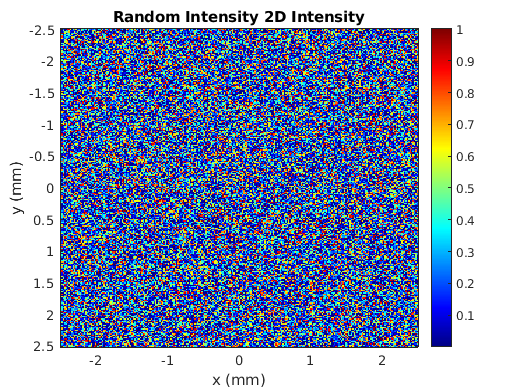

% Plot random intensity
amplitude = random_amplitude(gridcoords);
plot_2d_intensity(gridcoords, amplitude, 'Random Intensity');

drawnow;

%Task: Implement gain_sheet_saturable(coordinates, field,sat,alpha,power,size)
%Task: Implement propagate_roundtrip(coordinates, amplitude, power, aperture, R).

%Task: Simulate 100 bounces with the aperture radius (use a circular aperture) 
% approximately set to the width calculated above. Set  N_x, N_y = 0,
% so that the aperture is a simple circular hole. 

%Task: As you iterate the bounces, save the output power, 
%(1 - R) of the beam power, in an array. Plot the output power versus time. 
%If your simulation is successful, it should grow until being approximately
% the power you estimated above, then becoming stable in time.

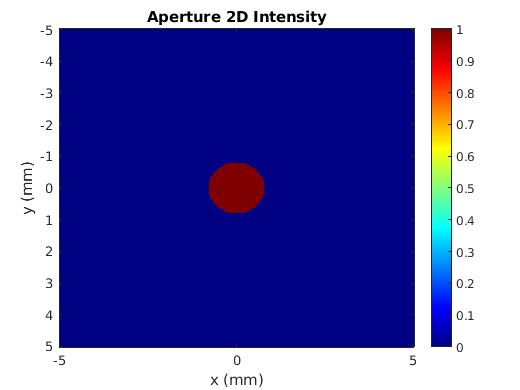

% Generate coordinates and an aperture that will produce a Gaussian
coordinates = generate_2d_coordinates(N, D);
aperture = grid_aperture(coordinates, %... purely circular aperture to produce lowest order mode, transverse intensity is a Gaussian);

% Display the aperture
plot_2d_intensity(coordinates, aperture, 'Aperture');

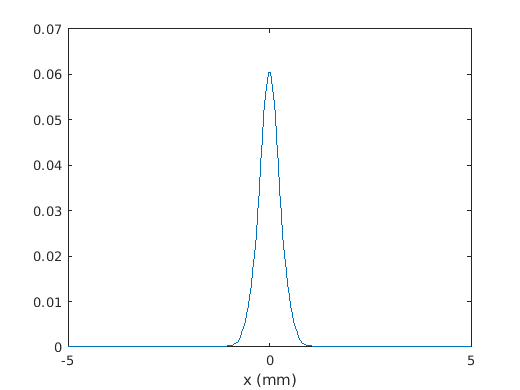

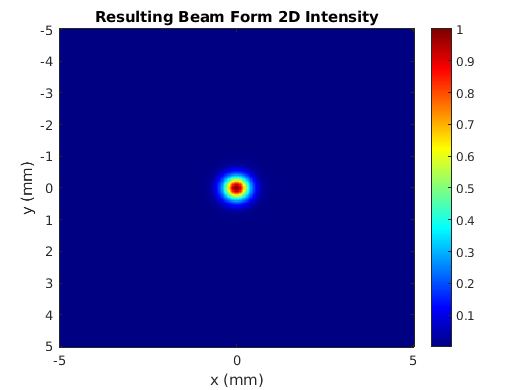

drawnow;

% Start with a random low power light field
amplitude = random_amplitude(coordinates);
power = power_random;

% Arrays to store simulation time and power output
powers = [];
ts = [0];

for i = 1:iterations
    [amplitude, power] = %... one roundtrip simulation iteration we just implemented
    
    powers = [powers, power * (1 - R)];
    ts = [ts, ts(end) + dt];
end

% Remove last element of ts as it's excess
ts(end) = [];

% Plot the mode 1D cross-section
figure;
title('Intensity Cross Section Gaussian-Like Cavity Mode');
plot(coordinates(128, :, 1) / millimeter, abs(normalize(amplitude(:, 128))).^2);
xlabel('x (mm)');
drawnow;

% Plot the mode 2D intensity
figure;
plot_2d_intensity(coordinates, amplitude, 'Resulting Beam Form');

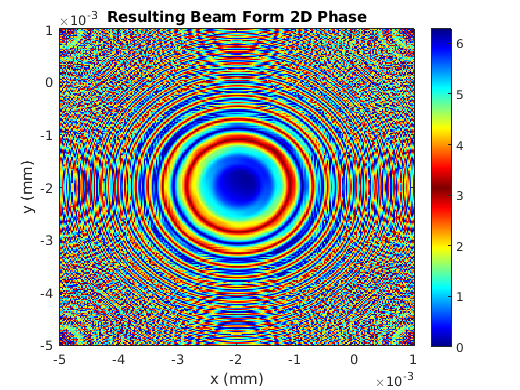

drawnow;

% Plot the mode 2D phase
figure;
plot_2d_phase(coordinates, amplitude, 'Resulting Beam Form');

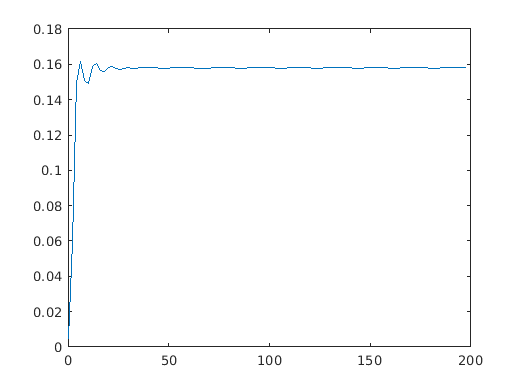

drawnow;

% Plot the power of the beam over time
figure;
title('Output Power Over Time');
ylabel('Power (W)');
xlabel('Time (ns)');
plot(ts * 1e9, powers); % Convert time to ns
saveas(gcf, 'power_over_time_example.png', 'png');

drawnow;

%Task: Implement beam_widths_with_40cm_lens(coordinates, ampl, plot = False) 
% this function should Fresnel propagate an input amplitude and coordinates after 
% being passed through an f = 40cm thin lens over some set of distances out to 90cm.

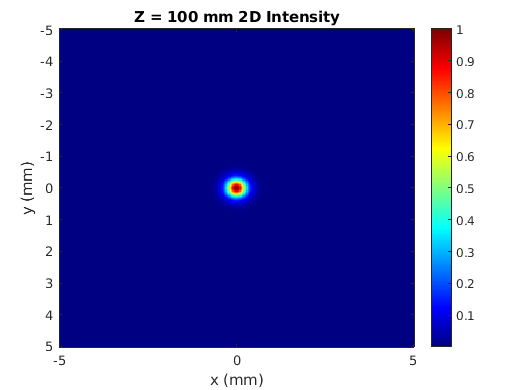

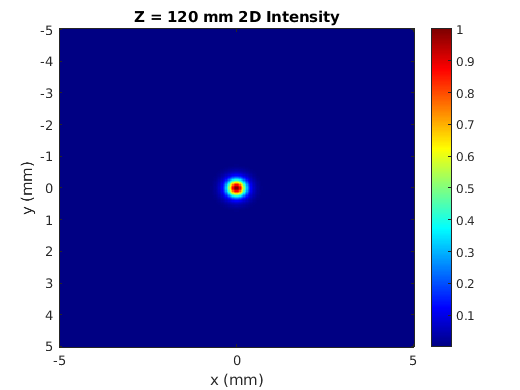

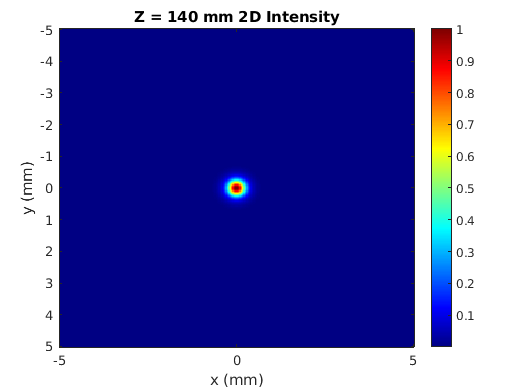

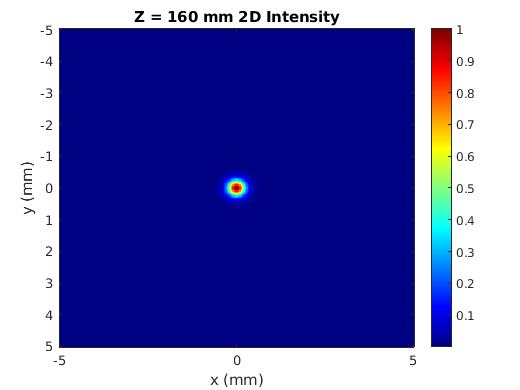

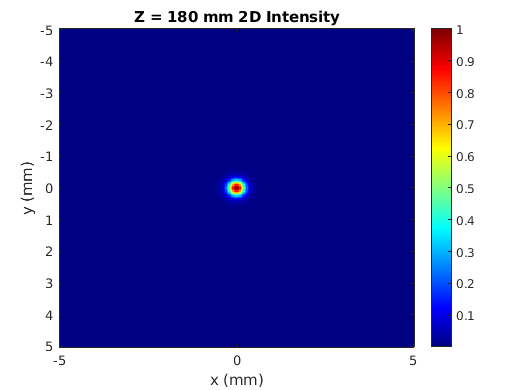

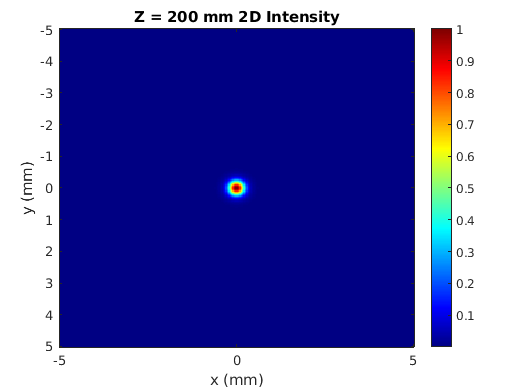

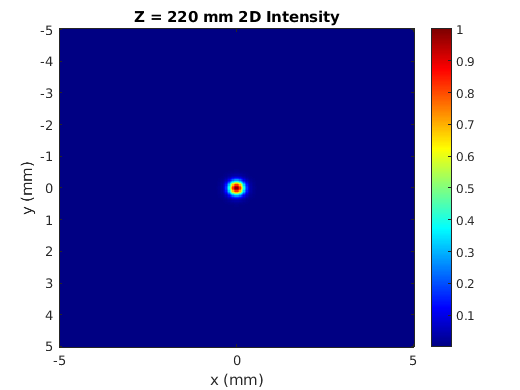

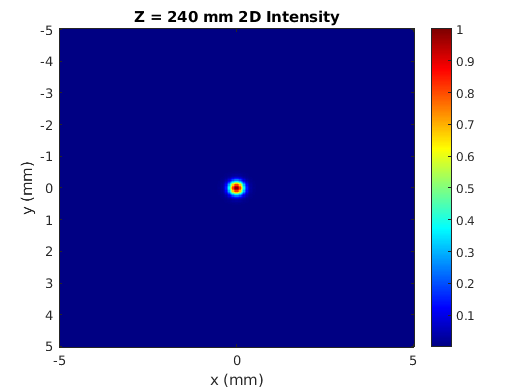

% Calculate an example Gaussian propagatng out of the cavity with 40cm
% lensing
[zs, wxs, wys] = beam_widths_with_40cm_lens(coordinates, amplitude, true);

%Task: implement fit_widths_data(zs, wxs, wys) which takes the propagation distances and transverse widths, 
%and fits two M2 model parameter sets (one for each transverse axis), 
% which should be returned. This should be similar to the implementation of CHW7.

%Task: Produce plots of the 2d beam intensity and phase for the nearly Gaussian mode 
% of your cavity. Use the above two functions to calculate the M2 
% of the beam in both transverse axes. Produce fitting plots like those of CHW7:

[cfx,cfy] = fit_widths_data(zs, wxs, wys,lamb)

cfx =     0.0004    1.6821    0.4332


cfy =     0.0004    1.6819    0.4332


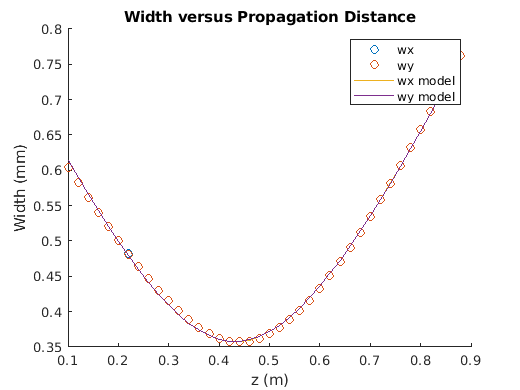


% Create a new figure
figure;

% Scatter plots for wxs and wys
scatter(zs, 2 * wxs / millimeter, 'DisplayName', 'wx'); % Scatter plot for wxs
hold on; % Hold the current plot
scatter(zs, 2 * wys / millimeter, 'DisplayName', 'wy'); % Scatter plot for wys

% Plot the model fits
plot(zs, W(zs, cfx(1), cfx(2), cfx(3), lamb) / millimeter, 'DisplayName', 'wx model'); % wx model
plot(zs, W(zs, cfy(1), cfy(2), cfy(3), lamb) / millimeter, 'DisplayName', 'wy model'); % wy model
hold off; % Release the hold

% Labeling the axes and adding title
xlabel('z (m)');
ylabel('Width (mm)');
title('Width versus Propagation Distance');
legend; 

% Saving the figure
saveas(gcf, 'width_versus_z_model_fit.png', 'png'); 


% Show the plot
shg; 

%Task: Introduce a spider_aperture or grid_aperture 
% (arm thickness of 0.01mm works for me) to your simulation, ie  
% N_x, N_y not 0, or N_arm not 0. These arms will block out lower order modes.
% You should also have to increase the aperture radius significantly to accommodate
% the higher order modes.

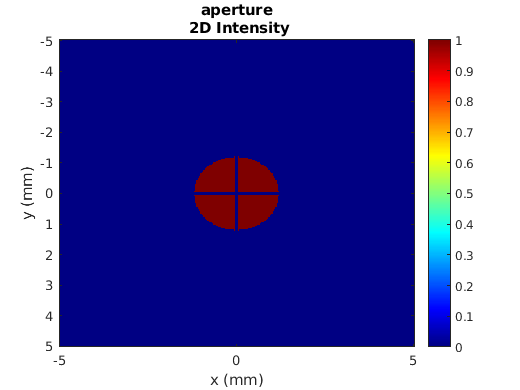

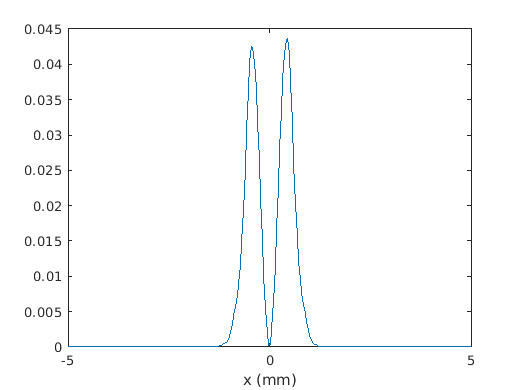

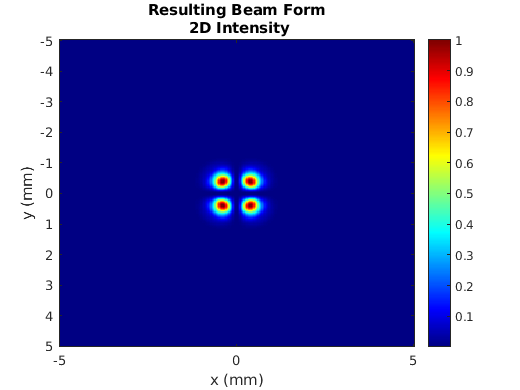

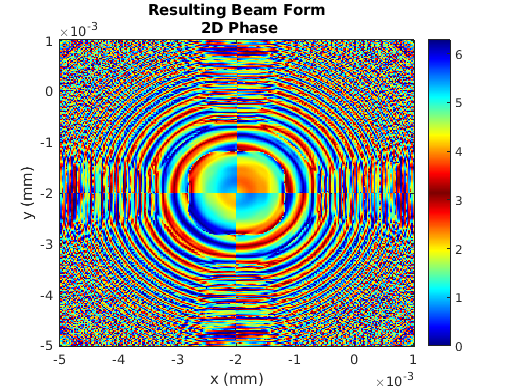

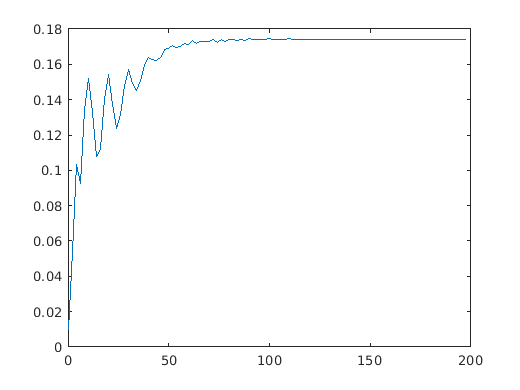

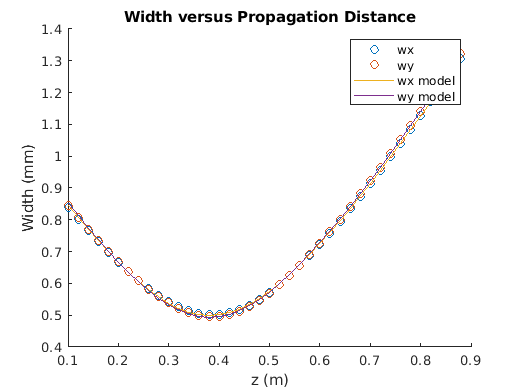

Fit Parameters (x/y)
    0.0005    3.7924    0.3827

    0.0005    3.8118    0.3824



%Use a function that is just the simulate and fit code to repeat for different apertures

sim_aperture(%...,lamb)

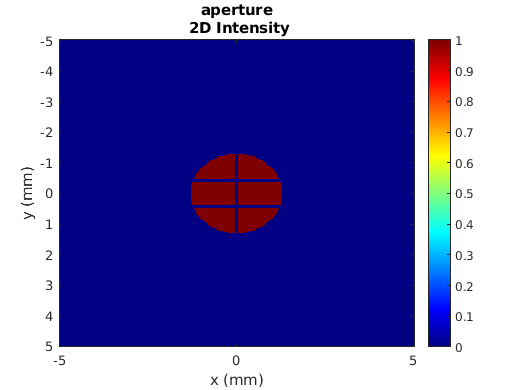

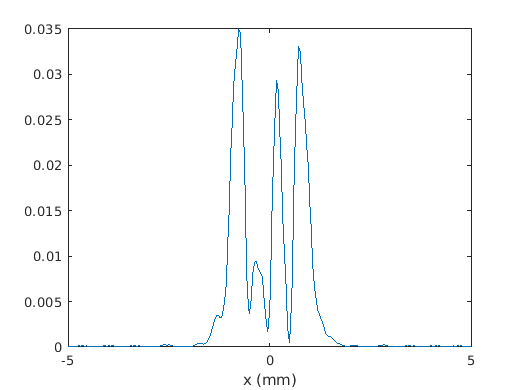

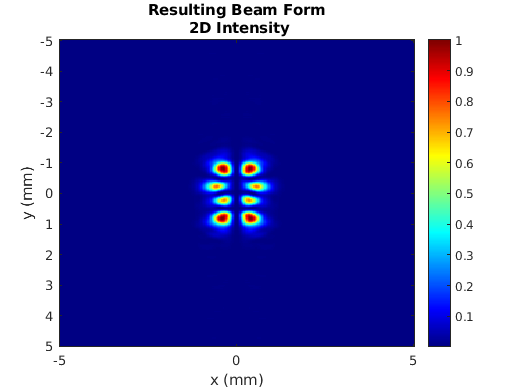

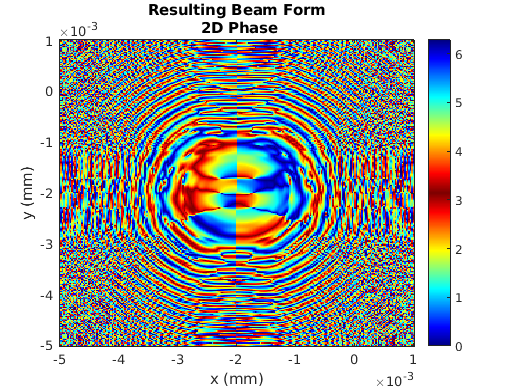

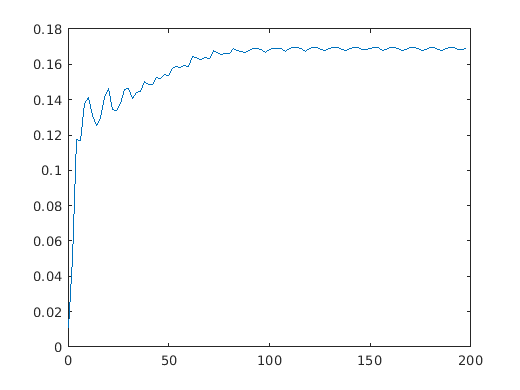

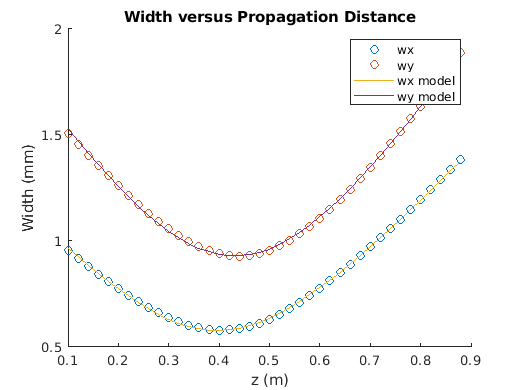

Fit Parameters (x/y)
    0.0006    4.7147    0.3985

    0.0009   10.6573    0.4321



sim_aperture(%...,lamb)

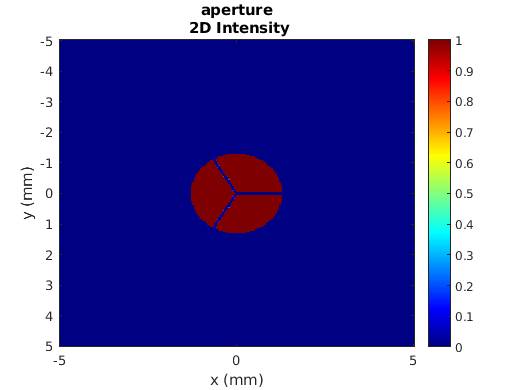

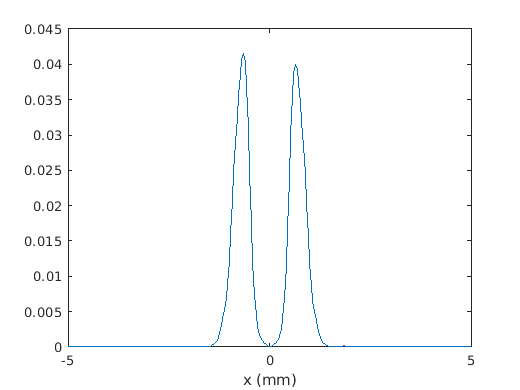

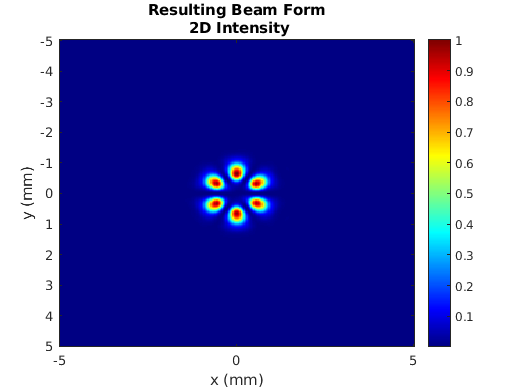

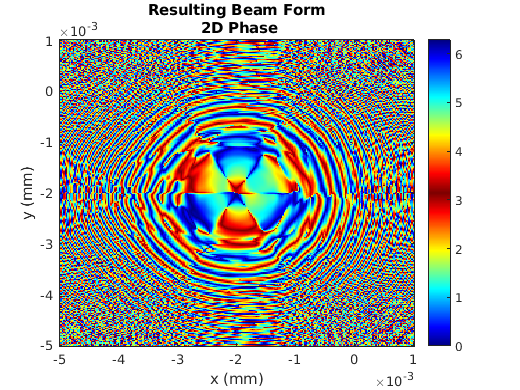

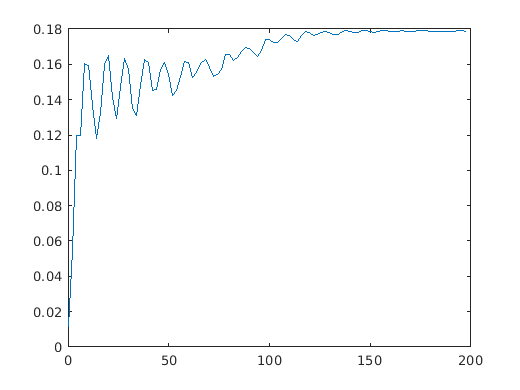

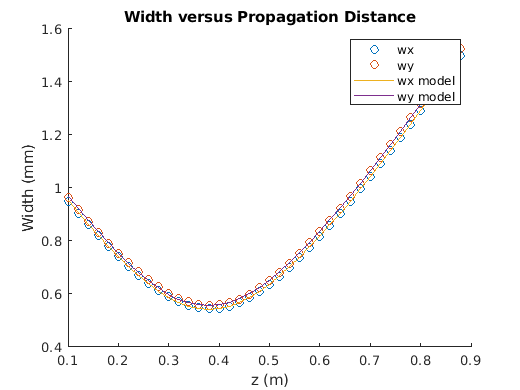

Fit Parameters (x/y)
    0.0005    4.7606    0.3804

    0.0006    4.9539    0.3794



sim_aperture(%...,lamb)